# Validation of Physics-Based Image Systems Simulation with 3D Scenes

## Figure 1 

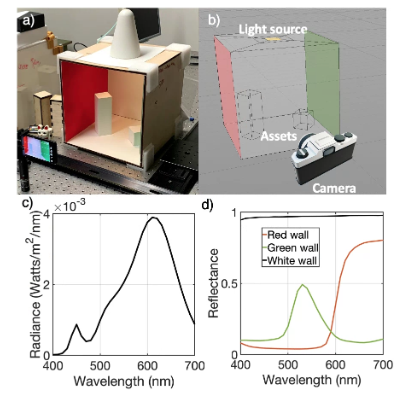

Fig. 1. Real and simulated Cornell box. (a) An image of the Cornell box and its light source in the lab. (b) Geometric representation of the Cornell box model and camera position in Cinema 4D. (c) Measured spectral power distribution of light source. (d) Measured spectral reflectance of white, red and green surfaces.

These figures simply plot the data we have stored.

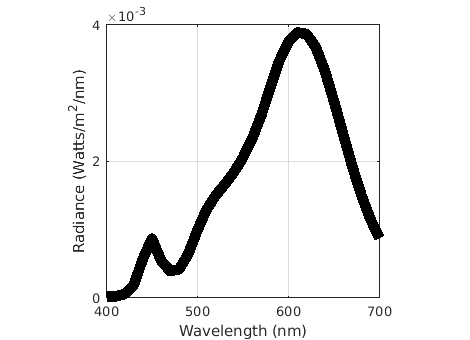

% Spectral reflectance
wave = 400:10:700;
refl = ieReadSpectra('cboxSurfaces', wave);
rRefl = refl(:, 1);
gRefl = refl(:, 2);
wRefl = refl(:, 3);

lightName = 'cbox-lights-1';
lgtSpd = ieReadSpectra(lightName, wave);


ieNewGraphWin;
plot(wave, lgtSpd, 'k', 'LineWidth', 8);
xlabel('Wavelength (nm)');
ylabel('Radiance (Watts/m^2/nm)');
xticks(400:100:700); xlim([400 700]);
ylim([0 4e-3]); yticks(0:2e-3:4e-3);
box on; grid on; axis square;

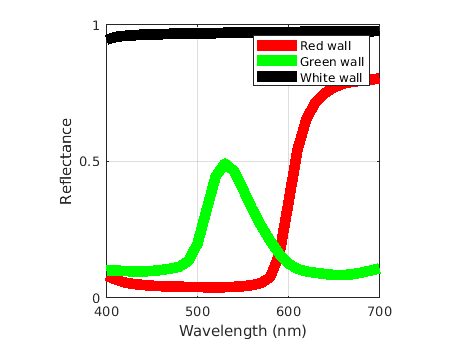


ieNewGraphWin;
hold all;
plot(wave, rRefl, 'r', 'LineWidth', 8);
plot(wave, gRefl, 'g', 'LineWidth', 8);
plot(wave, wRefl, 'k', 'LineWidth', 8);
legend('Red wall', 'Green wall', 'White wall');
xlabel('Wavelength (nm)');
ylabel('Reflectance');
xticks(400:100:700); xlim([400 700]);
ylim([0 1]); yticks(0:0.5:1);
box on; grid on; axis square;

## Figure 2

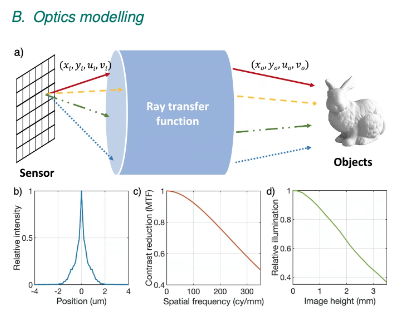

Fig. 2. The ray transfer method of lens modeling. (a) We use a Zemax ’black-box model’ to estimate the ray-transfer function. This function describes the mapping between rays from the sensor plane that are incident at the entrance pupil, through the unknown optics, to rays in a plane after exiting from the optics. The position of the incident and output rays are described by the four-dimensional vectors, (xi, yi, ui, vi) and (xo, yo, uo, vo). The first two entries define the position of the ray in the aperture, and the second two entries define the ray direction. We use Zemax to calculate 128,561 input-output ray pairs. We then fit a set of four polynomials relating the four input ray parameters to each of the four output ray parameters (Equation 1). (b-d) The Zemax model generates a line spread function (LSF) , modulation transfer function (MTF) and relative illumination function, all at 550 nm. The ray-transfer function  implementation in PBRT matches the Zemax calculations on these functions [32]. We evaluate the model accuracy by comparing measurements with these simulations.

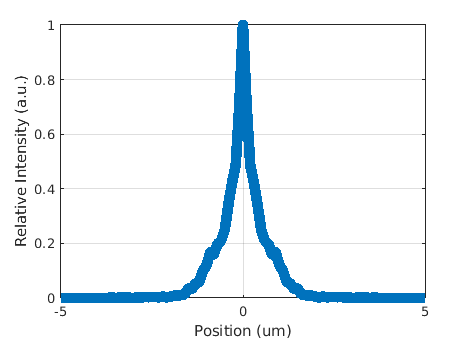

% LSF, MTF, lens vignetting
zemaxPath = fullfile(cboxRootPath, 'data', 'lens',...
                        'zemax');
                    
%% Read LSF
lsfName = 'GeometricLSP.txt';
% A n x 5 matrix, which are: position, LSFX, erfX (?), LSFY, erfY
lsfRaw = readmatrix(fullfile(zemaxPath, lsfName));
lsfPos = lsfRaw(:, 1);
lsfX = lsfRaw(:, 2); lsfY = lsfRaw(:,4); % Same

ieNewGraphWin; 
hold all;
plot(lsfPos, lsfX, 'LineWidth', 8);
grid on; box on; 
xlabel('Position (um)'); ylabel('Relative Intensity (a.u.)');

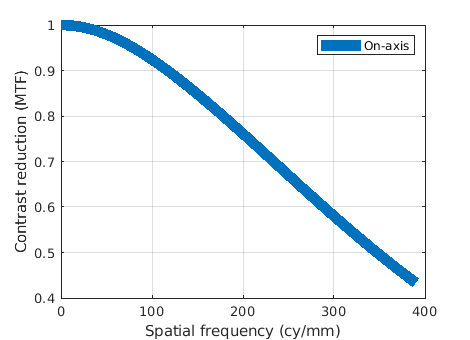


%% Read MTF
mtfName = 'GeometricMTF.txt';
mtfRaw = readmatrix(fullfile(zemaxPath, mtfName));
%{
1:81, 84:164, 167:247, 250:330, 333:413, 416:496
%}
validRows = {[1:81]};

ieNewGraphWin;hold all;
for ii=1:numel(validRows)
    plot(mtfRaw(validRows{ii}, 1), mtfRaw(validRows{ii}, 3), 'LineWidth', 8);
end
grid on; box on;
xlabel('Spatial frequency (cy/mm)'); ylabel('Contrast reduction (MTF)');
legend('On-axis');

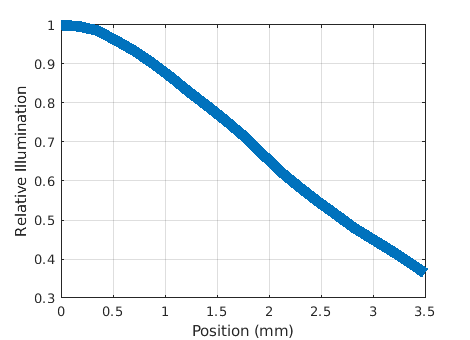

    
%% Relative illumination
riName = 'RI.txt';
riRaw = readmatrix(fullfile(zemaxPath, riName));
pixPos = riRaw(:,1);
lensVignet = riRaw(:,2);
ieNewGraphWin; hold all;
plot(pixPos, lensVignet, 'LineWidth', 8, 'go');
grid on; box on;
xlabel('Position (mm)'); ylabel('Relative Illumination');
xlim([0 3.5])